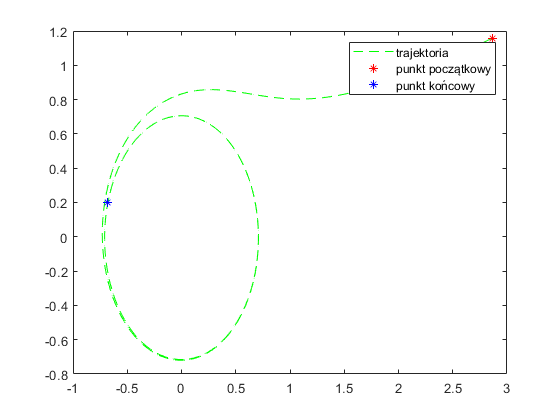

initial_cond = [8,8 ; 0,0.5 ; 10,0 ; 0.001,0.01];
example = 1;
data = RK4(0.01, initial_cond(example,:));
%plot(t(1:end-1), data)
plot(data(:,2), data(:,1), '--g', data(1,2), data(1,1), '*r', data(end,2), data(end,1), '*b')
legend('trajektoria', 'punkt początkowy', 'punkt końcowy');

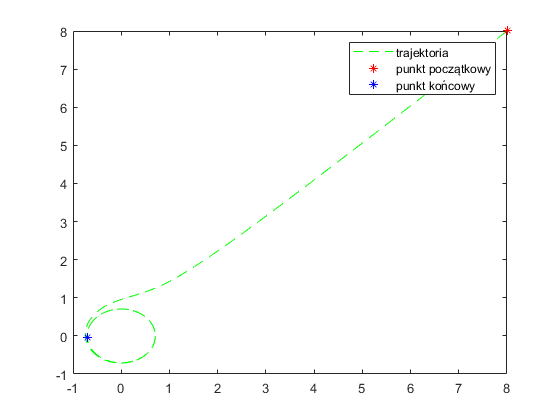


fun = @(t,x) [x(2) + x(1)*(0.5 - x(1).^2 - x(2).^2); -x(1) + x(2)*(0.5 - x(1).^2 - x(2).^2)];

tspan = [0, 15];
[t, data] = ode45(fun, tspan, initial_cond(example,:));
plot(data(:,2), data(:,1), '--g', data(1,2), data(1,1), '*r', data(end,2), data(end,1), '*b')
legend('trajektoria', 'punkt początkowy', 'punkt końcowy');

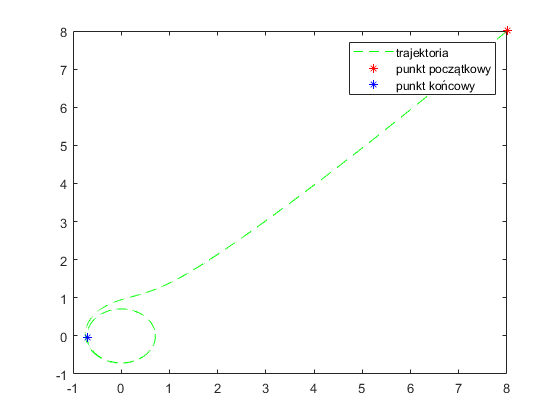



data = predictor_corrector(0.001, initial_cond(example,:));
plot(data(:,2), data(:,1), '--g', data(1,2), data(1,1), '*r', data(end,2), data(end,1), '*b')
legend('trajektoria', 'punkt początkowy', 'punkt końcowy');